cd 'C:\Users\elite\Desktop\school\robotics project\MiniVIE'
MiniVIE.configurePath

[MiniVIE.m] Configured MiniVIE path at: C:\Users\elite\Desktop\school\robotics project\MiniVIE



hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] No file  found
[MyoUdp] UDP Comms already initialized


[MiniVIE.m] Configured MiniVIE path at: C:\Users\elite\Desktop\school\robotics project\MiniVIE
[UserConfig.m] No file  found


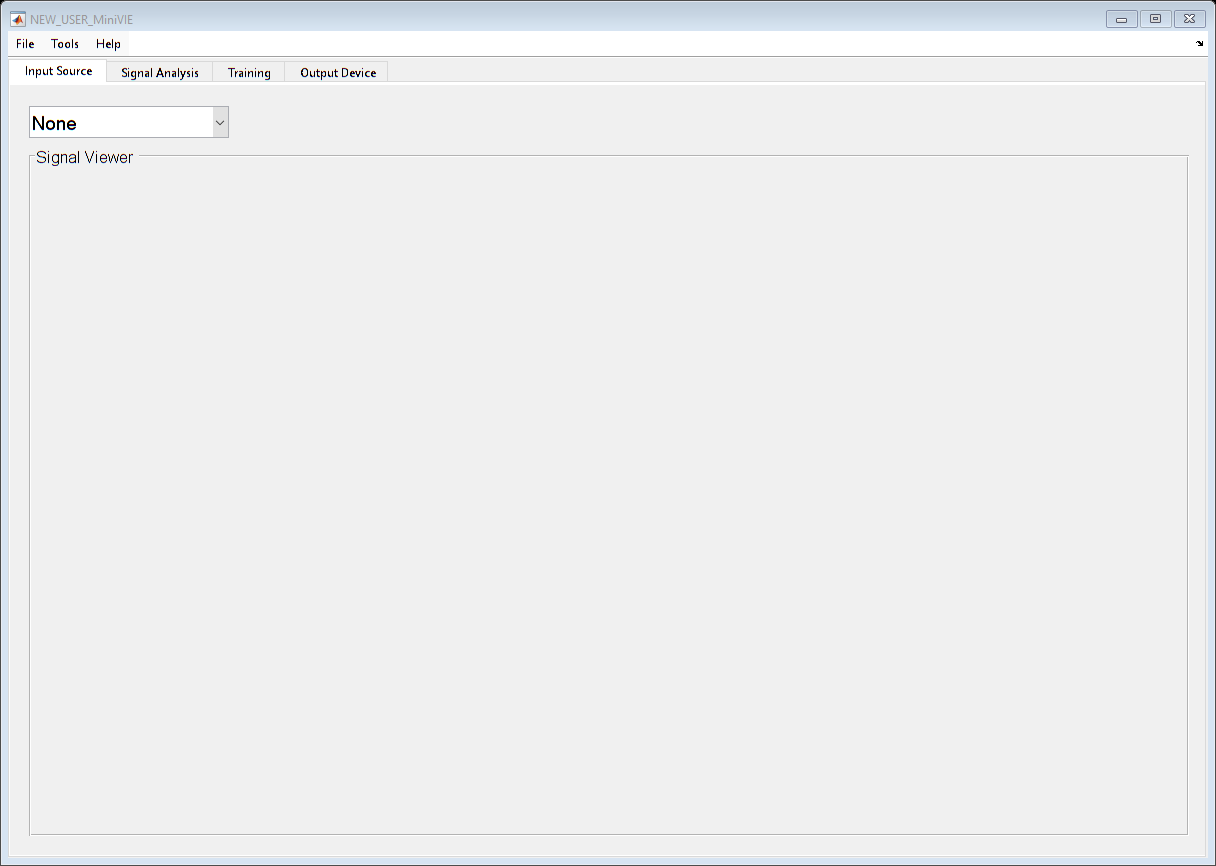

obj = MiniVIE;

% matlab.engine.shareEngine;
% matlab.engine.engineName
% 
% sprintf('Please connect to the engine using the python script')
% pause();

% CHANGE THIS TO MATCH YOUR TRAINING DATA FILE
myDataFilename = '../train.trainingData';
 
% Load training data file
hData = PatternRecognition.TrainingData();

[TrainingData] Creating Empty Training Data Object


hData.loadTrainingData(myDataFilename);

[TrainingData] Loading file: "../train.trainingData"
[TrainingData] Loading 2902 Samples
[TrainingData] Setting window size to 250.
[TrainingData] Sample rate empty.  Assuming 1000Hz


 
% Create EMG Myo Interface Object
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] No file  found
[MyoUdp] UDP Comms already initialized


 
% Create LDA Classifier Object
hLda = SignalAnalysis.Lda;
hLda.initialize(hData);

[UserConfig.m] No file  found
[UserConfig.m] No file  found


hLda.train();

Training LDA with 1773 Samples (1 = 223; 2 = 211; 3 = 256; 4 = 213; 5 = 213; 6 = 216; 7 = 228; 8 = 0; 9 = 213; )
Active Channels are: [ 1 2 3 4 5 6 7 8 ]
[Lda] Classes with no data [ 8 ] 


hLda.computeError();

Percent correctly classified:   99.2 %  (1773 samples)
       Elbow Flexion Class accuracy:	   99.1 % 	( 221 of  223)
     Elbow Extension Class accuracy:	   97.6 % 	( 206 of  211)
         Power Grasp Class accuracy:	  100.0 % 	( 256 of  256)
       Wrist Flex In Class accuracy:	  100.0 % 	( 213 of  213)
    Wrist Extend Out Class accuracy:	  100.0 % 	( 213 of  213)
     Wrist Abduction Class accuracy:	   98.6 % 	( 213 of  216)
     Wrist Adduction Class accuracy:	   98.2 % 	( 224 of  228)
           Hand Open Class accuracy:	    0.0 % 	(   0 of    0)
         No Movement Class accuracy:	  100.0 % 	( 213 of  213)


 
StartStopForm([]); % initialize a small gui utility to control a while loop

% MATLAB script to send data to Python server
% Establish connection to the Python server
host = 'localhost';
port = 65432;
client = tcpclient(host, port);
% Function to send data to the Python server
function send_data_to_server(client, value)
    write(client, num2str(value), 'string');
end

while StartStopForm
        
    % Get the appropriate number of EMG samples for the 8 myo channels
    emgData = hMyo.getData(hLda.NumSamplesPerWindow,1:8);
    
    % Extract features and classify
    features2D = hLda.extractfeatures(emgData);
    [classDecision, voteDecision] = hLda.classify(reshape(features2D',[],1));
    
    % Display the resulting class number and name
    classNames = hLda.getClassNames;
    className = classNames{classDecision};
    %fprintf('Class=%2d; Class = %16s;\n',classDecision,className);
    
    % refresh the display
    drawnow;

    send_data_to_server(client, className)

    pause(.1)
end


clear client